# CDL Channel Model Customization with Ray Tracing

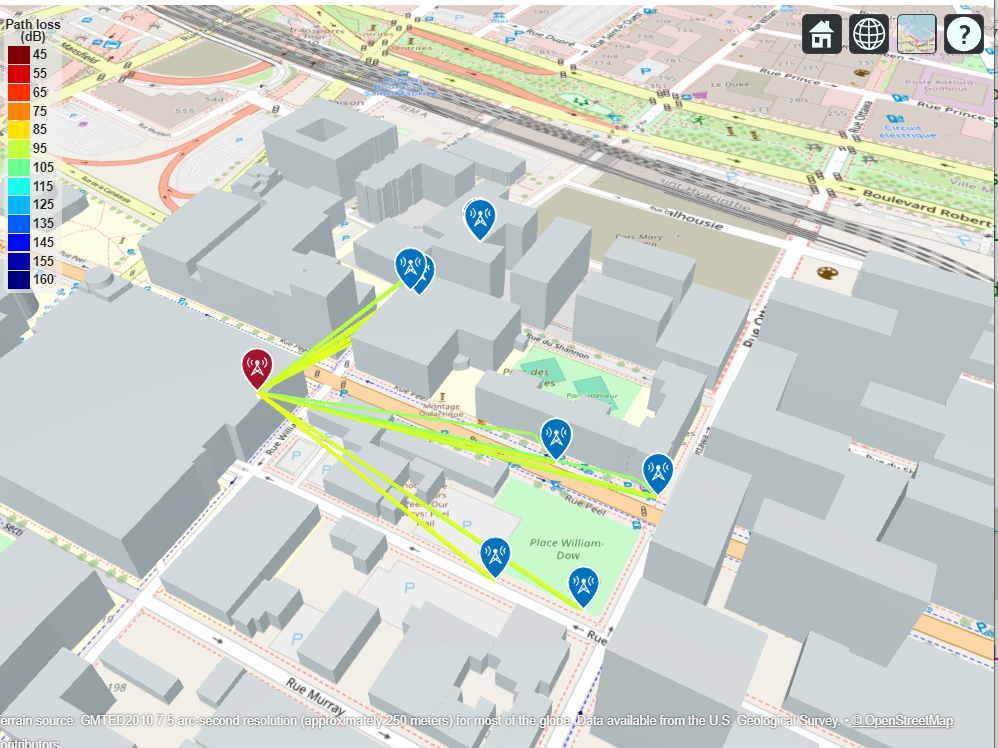

clear;
% Change the current folder to the folder of this file.
if(~isdeployed)
  cd(fileparts(matlab.desktop.editor.getActiveFilename));
end


addpath('helper')
addpath('osmFile')

## Base Station and UE Configuration

The example assumes that both the base station and the UE use rectangular arrays. The array orientations are specified as a pair of values representing azimuth and elevation. Both angles are in degrees.

UE_grid = cell(2);
UE_grid{1}.street = 'Peel'; 
    UE_grid{1}.vertice{1}.location = [45.493717,-73.560149]; % lat, lon
    UE_grid{1}.vertice{2}.location = [45.494248,-73.559836];
    UE_grid{1}.vertice{3}.location = [45.494132,-73.559423];
    UE_grid{1}.vertice{4}.location = [45.493636,-73.559890];
UE_grid{2}.street = 'William'; 
    UE_grid{2}.vertice{1}.location = [45.495371,-73.560918];
    UE_grid{2}.vertice{2}.location = [45.495328,-73.560852];
    UE_grid{2}.vertice{3}.location = [45.495774,-73.560438];
    UE_grid{2}.vertice{4}.location = [45.495785,-73.560452];

%%% Visualize positions
% Extract coordinates from UE_grid
% latitudes = [UE_grid{1}.vertice{1}.location(1), UE_grid{1}.vertice{2}.location(1), ...
%              UE_grid{1}.vertice{3}.location(1), UE_grid{1}.vertice{4}.location(1), ...
%              UE_grid{1}.vertice{1}.location(1)]; % Closing the loop
% longitudes = [UE_grid{1}.vertice{2}.location(2), UE_grid{1}.vertice{2}.location(2), ...
%               UE_grid{1}.vertice{3}.location(2), UE_grid{1}.vertice{4}.location(2), ...
%               UE_grid{1}.vertice{2}.location(2)]; % Closing the loop
% % Create a geographic plot
% figure;
% geoplot(latitudes, longitudes, '-o');
% title('Vertices of the Street: Peel');
% grid on;
% Create a geographic plot
% figure;
% geoplot(latitudes, longitudes, '-o');
% title('Vertices of the Street: William');
% grid on;

## Import and Visualize 3-D Environment with Buildings for Ray Tracing

Launch Site Viewer with buildings in ETS. For more information about the osm file, see [1].

if exist('viewer','var') && isvalid(viewer) % viewer handle exists and viewer window is open
    clearMap(viewer);
else
    viewer = siteviewer("Basemap","openstreetmap","Buildings","map.osm");    
end

## Create Base Station and UE

Locate the base station and the UE on the map.

fc = 3.4e9;                             % carrier frequency (Hz)  2.4e9 2.6e9?
v = 15 ; % UE velocity in km/h
c = physconst('lightspeed'); % speed of light in m/s
fd = (v*1000/3600)/c*fc;     % UE max Doppler frequency in Hz  
                             %     fd=47.3 with v=15km/h
                             %     fd=126  with v=40km/h
onlyLOS_flag = 0; % 1 if only consider UEs that has LOS in its rays

bsPosition = [45.494449,-73.561667];  % lat, lon
bsAntSize = [1 1]; % [8 8];                    % number of rows and columns in rectangular array (base station)
bsArrayOrientation = [-30 0].';       % azimuth (0 deg is East, 90 deg is North) and elevation (positive points upwards) in deg

reflectionsOrder = 5;                 % number of reflections for ray tracing analysis (0 for LOS)
 
% Bandwidth configuration, required to set the channel sampling rate and for perfect channel estimation
SCS = 30; % 15; % subcarrier spacing
NRB = 51; % number of resource blocks, SCS*NRB*12 MHz bandwidth for transmission

bsSite = txsite("Name","Base station", ...
    "Latitude",bsPosition(1),"Longitude",bsPosition(2),...
    "AntennaAngle",bsArrayOrientation(1:2),...
    "AntennaHeight",4,...  % in m
    "TransmitterFrequency",fc);
show(bsSite);

a_1 = 1;
a_2 = 1;
for i = 1: length(UE_grid)
    UE_grid{i}.pointInside = gen_pointInside(UE_grid{i}, a_1, a_2); %
end
num_UE = 0; % total number of UEs
for idx_grid = 1:length(UE_grid)
    num_UE = num_UE + size(UE_grid{idx_grid}.pointInside,1);
end

% idx_save = check_save_idx(['../Data/ver', num2str(idxFolder), '_/',num2str(0),'dB'], '_mapBaseData')
idxFolder = check_save_idx_folder("GeneratedChannel/", 'ver','_')

idxFolder = 4

ueAntSize = [1 1]; % [2 2];                    % number of rows and columns in rectangular array (UE).
ueArrayOrientation = [180 45].';      % azimuth (0 deg is East, 90 deg is North) and elevation (positive points upwards)  in deg
pm = propagationModel("raytracing","Method","sbr","MaxNumReflections",reflectionsOrder);
lambda = c/fc;
ofdmInfo = nrOFDMInfo(NRB,SCS);
[txWaveform, carrier, dmrsSymbols, dmrsIndices] = wave_gen();

% UE array (single panel)
ueArray = phased.NRRectangularPanelArray('Size',[ueAntSize(1:2) 1 1],'Spacing', [0.5*lambda*[1 1] 1 1]);
ueArray.ElementSet = {phased.IsotropicAntennaElement};   % isotropic antenna element
% Base station array (single panel)
bsArray = phased.NRRectangularPanelArray('Size',[bsAntSize(1:2) 1 1],'Spacing', [0.5*lambda*[1 1] 1 1]);
bsArray.ElementSet = {phased.IsotropicAntennaElement};   % isotropic antenna element;  {phased.NRAntennaElement('PolarizationAngle',-45) phased.NRAntennaElement('PolarizationAngle',45)}; % cross polarized elements

OFDM_span = 28;     % OFDM symbols
OFDM_current = 14;  % estimated channel at current time slot
OFDM_future  = OFDM_span - OFDM_current; % future channel (need to be forecast/predict)
considerCP = true; 
return_timeDomain = true;
channel_SampleDensity = inf; % default = 64

SNRdB = 0:5:30; 
mse_lin  = zeros(1, length(SNRdB));
mse_prac = zeros(1, length(SNRdB));
nmse_lin  = zeros(1, length(SNRdB));
nmse_prac = zeros(1, length(SNRdB));
for idx_SNR = 1: length(SNRdB)
    snr = SNRdB(idx_SNR);
    fprintf('SNR: %d / %d', snr, SNRdB(end));
    SNR = 10^(snr/10); % Calculate linear SNR
    N0 = 1/sqrt(2*double(ofdmInfo.Nfft)*SNR); % simParameters.NRxAnts = 1

    H_true = zeros(OFDM_span,NRB*12,num_UE);    % symbol (OFDM_span) x subc x num_UE
    H_time = zeros(15360* OFDM_span/14 , num_UE);            % 15360*n_slot x num_UE

    % Y           = zeros(OFDM_current,NRB*12,num_UE);
    H_equalized = zeros(OFDM_current,NRB*12,num_UE);  % current symbol (14) x subc x num_UE
    H_linear    = zeros(OFDM_current,NRB*12,num_UE);
    H_practical = zeros(OFDM_current,NRB*12,num_UE);     % channel estimated by Matlab built-in

    idx_UE = 1;
    for idx_grid = 1:length(UE_grid)
        for idx_point = 1:size(UE_grid{idx_grid}.pointInside,1)
            
            if (idx_point ==1)||(idx_point==num_UE/2)||(idx_point==1+a_1)||(idx_point==num_UE/2-a_2)
                plot_flag = 1;
            else
                plot_flag = 0;
            end
            UE_grid = setUE_grid(UE_grid, plot_flag, idx_grid, idx_point, idx_UE, bsSite, pm, onlyLOS_flag, ueArray, bsArray, fc, fd, ofdmInfo, ueArrayOrientation, bsArrayOrientation, channel_SampleDensity);
            
            txWaveform1 = [];
            for idx_slot = 1: (OFDM_span/14)
                txWaveform1 = [txWaveform1; txWaveform];
            end
            
            [rxWaveform,pathGains,sampleTimes] = UE_grid{idx_grid}.channel{idx_point}(txWaveform1);
            
            % H_true
            % Get path filters for perfect channel estimation
            pathFilters = getPathFilters(UE_grid{idx_grid}.channel{idx_point});
            [offset,~] = nrPerfectTimingEstimate(pathGains,pathFilters);
            rxWaveform = rxWaveform(1+offset:end, :);
                        
            [H_true_n, H_time_n] = nrPerfectChannelEstimate_custom(carrier,pathGains, ...
                pathFilters,offset,sampleTimes, OFDM_span, considerCP, return_timeDomain); 
                % OFDM_span, considerCP, return_timeDomain at 6th, 7th, 8th of the input 
                % 612x14
            
            H_true(:,:,idx_UE) = H_true_n.'; % nOFDMsymb x 612
            H_time(:, idx_UE)  = H_time_n;
            
            % approach 3
            rxGrid1 = nrOFDMDemodulate(carrier,rxWaveform);
            if OFDM_span>14
                rxGrid = rxGrid1(:, 1:14);
            else
                rxGrid = rxGrid1;
            end
            % Pad the grid with zeros in case an incomplete slot has been demodulated
            [K,L,R] = size(rxGrid);
            if (L < carrier.SymbolsPerSlot)
                rxGrid = cat(2,rxGrid,zeros(K,carrier.SymbolsPerSlot-L,R));
            end
            rxGrid  = awgn(rxGrid,snr,'measured');
            % Y(:,:,idx_UE) = rxGrid'; % 14x612

            [H_equalized_n, H_linear_n] = Lin_Interpolate(rxGrid, dmrsIndices, dmrsSymbols);
            
            H_equalized(:,:,idx_UE) = H_equalized_n.';  % 14x612
            H_linear(:,:,idx_UE)    = H_linear_n.';     % 14x612
            
            % H_practical (channel estimation by Matlab built-in)
            H_practical(:,:,idx_UE) = nrChannelEstimate(rxGrid, dmrsIndices, dmrsSymbols).';

            if mod(idx_UE,200)==0
                fprintf('UE no %d / %d \n', idx_UE, num_UE);
            end
            
            idx_UE = idx_UE + 1;
        end
    end

    % shuff_flag = 0; 
    % flag_split = 0;    % split real/imag parts

    save_data(H_true, H_time, H_equalized, H_linear, H_practical, OFDM_current, idxFolder, snr); % add shuff_flag, flag_split if =1

    temp_true = H_true(1:OFDM_current,:,:);
    norm_squared = mean(temp_true(:).^2);
    mse_lin(idx_SNR)  = mean((temp_true(:)-H_linear(:)).^2);
    nmse_lin(idx_SNR) = mse_lin(idx_SNR)/norm_squared;

    mse_prac(idx_SNR) = mean((temp_true(:)-H_practical(:)).^2);
    nmse_prac(idx_SNR) = mse_prac(idx_SNR)/norm_squared;
end

SNR: 0 / 30SNR: 5 / 30SNR: 10 / 30SNR: 15 / 30SNR: 20 / 30SNR: 25 / 30SNR: 30 / 30

figure;
plot(SNRdB, nmse_prac, 'DisplayName', 'Practical');

hold on;
plot(SNRdB, nmse_lin, 'DisplayName', 'LS + LI');

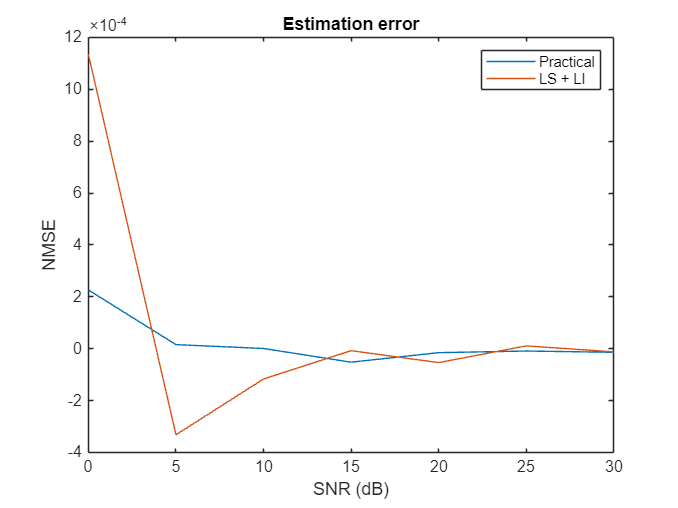

xlabel('SNR (dB)');
ylabel('NMSE');
legend;
title('Estimation error');

save(['generatedChannel/ver', num2str(idxFolder),'_/NMSE.mat'], 'mse_prac', 'nmse_prac', 'mse_lin', 'nmse_lin')

% add readme.txt
% Define the file name and open it for writing ('w' mode creates the file if it doesn't exist)
fileID = fopen(['generatedChannel/ver', num2str(idxFolder),'_/readme.txt'], 'w');  

% Check if the file was opened successfully
if fileID == -1
    error('Cannot open or create the file for writing.');
end
% Define the content to write to the file
content = ['This file is generated by mapBase_v1.mlx', newline, ...
           '1. fc: ', num2str(fc/1e9), ' GHz' newline, ...
           '2. reflection order: ', num2str(reflectionsOrder), newline,...
           '3. UE velocity: ', num2str(v) , ' km/h', newline,...
           '4. Maximum Doppler: ', num2str(fd), ' Hz', newline,...
           '5. Channel spans in ', num2str(OFDM_span), ' OFDM symbols', newline,...
           '6. channel_SampleDensity = ', num2str(channel_SampleDensity), newline];
% Write the content to the file
fprintf(fileID, '%s', content);
% Close the file
fclose(fileID);
disp('readme.txt file created successfully.');

readme.txt file created successfully.


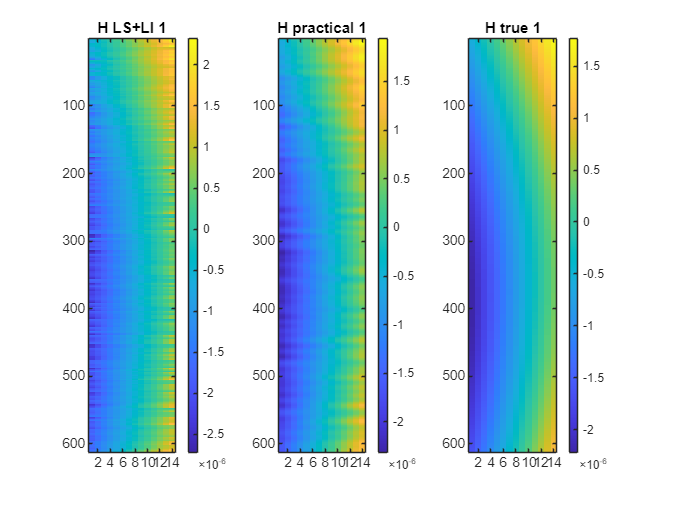

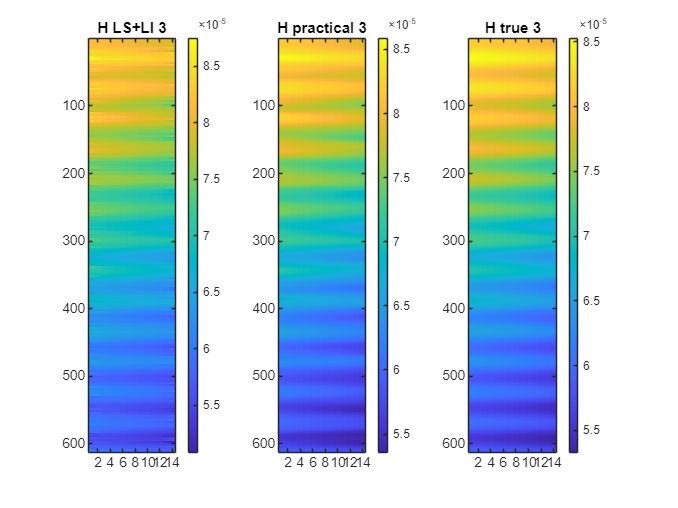

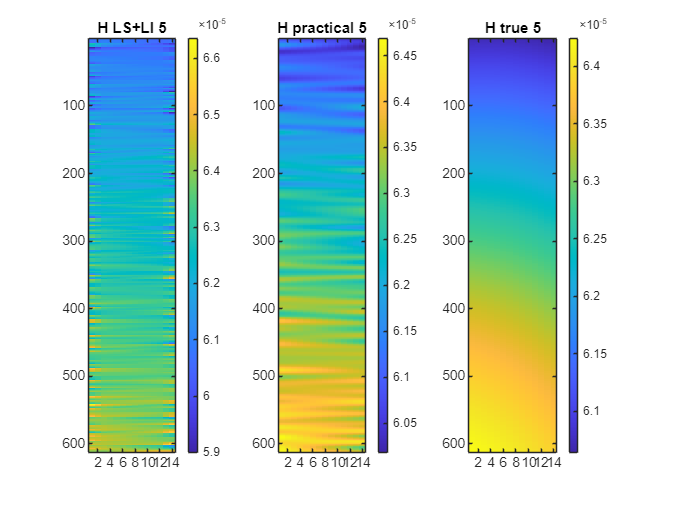

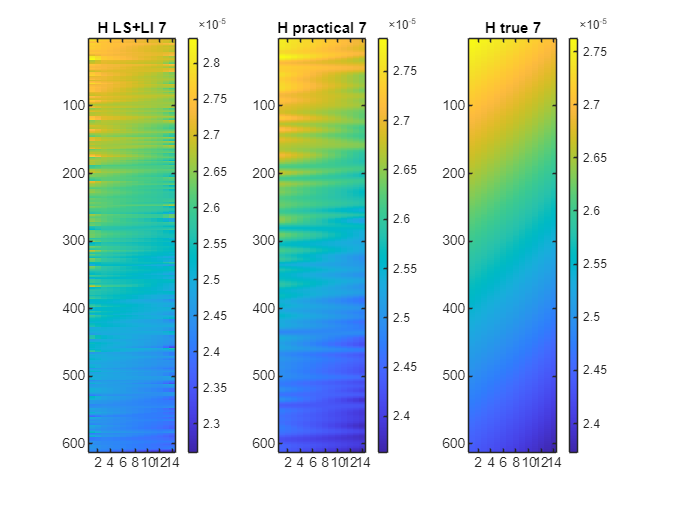

% snr = 30;
% load(['generatedChannel/ver', num2str(idxFolder), '_/', num2str(snr), 'dB/mapBaseData.mat']);
% 
for i = 1:ceil(size(H_true,3)/6):size(H_true,3)
    figure
    subplot(1,3,1);
    imagesc(real(H_linear(:,:,i)).')
    colorbar
    title("H LS+LI " + i);

    subplot(1,3,2);
    imagesc(real(H_practical(:,:,i)).')
    colorbar
    title("H practical " + i);

    subplot(1,3,3);
    imagesc(real(H_true(1:14,:,i)).')
    colorbar
    title("H true " + i);
end

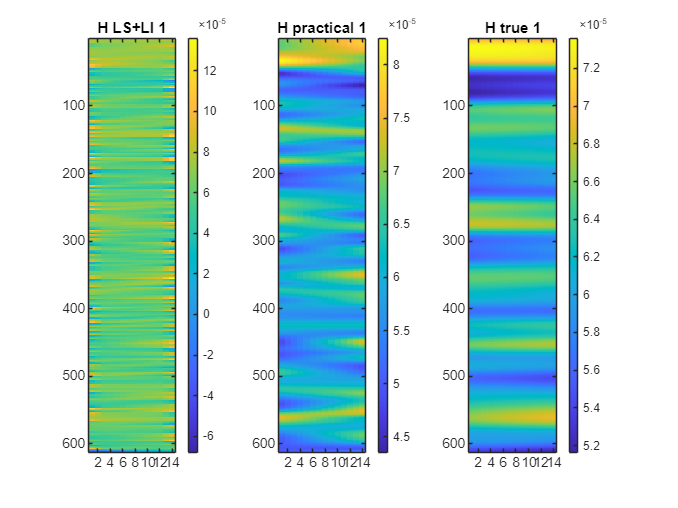

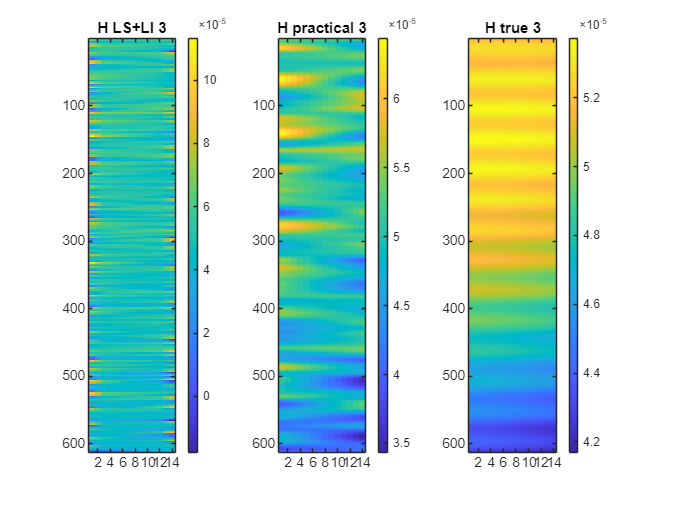

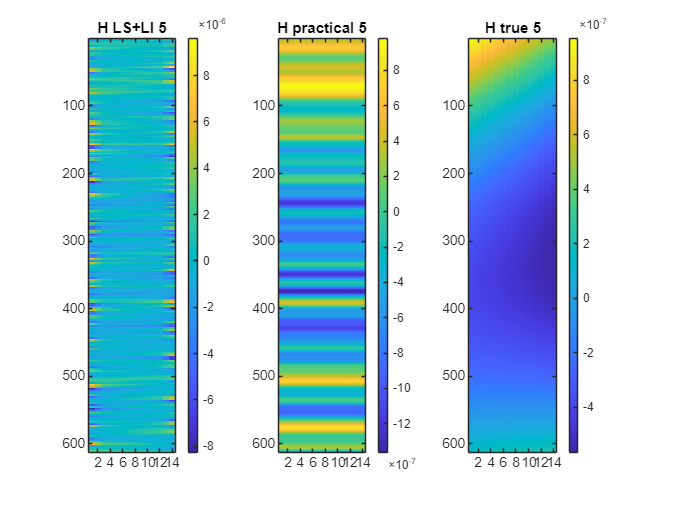

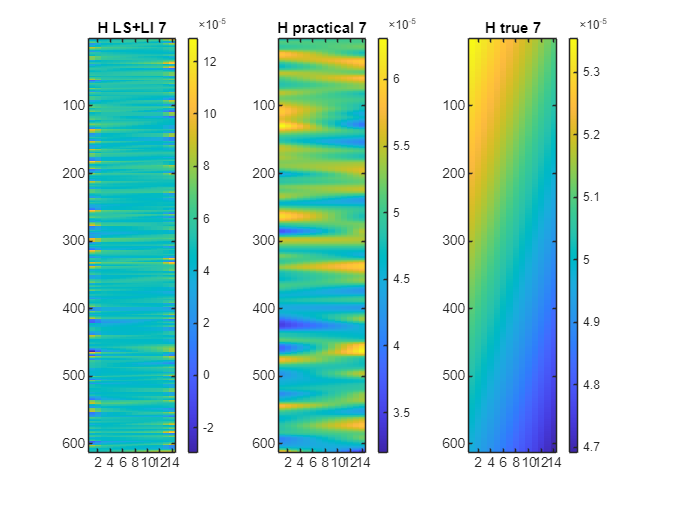

snr = 0;
load(['generatedChannel/ver', num2str(idxFolder), '_/', num2str(snr), 'dB/mapBaseData.mat']);
% 
for i = 1:ceil(size(H_true,3)/6):size(H_true,3)
    figure
    subplot(1,3,1);
    imagesc(real(H_linear(:,:,i)).')
    colorbar
    title("H LS+LI " + i);

    subplot(1,3,2);
    imagesc(real(H_practical(:,:,i)).')
    colorbar
    title("H practical " + i);

    subplot(1,3,3);
    imagesc(real(H_true(1:14,:,i)).')
    colorbar
    title("H true " + i);
end

% for i = 1:200:size(H_data,4)
%     figure
%     surf((real(H_data(:,:,1,i))));
%     title("Real Part of Channel Response (1^{st} tx - 1^{st} rx antenna) of channel " + i);
% 
%     surf(pow2db(abs(complex(H_data(:,:,1,i),H_data(:,:,2,i))).^2));
%     title("Channel Magnitude Response (1^{st} tx - 1^{st} rx antenna) of channel " + i);
% 
%     shading('flat');
%     xlabel('OFDM Symbols');ylabel('Subcarriers');zlabel('Magnitude Squared (dB)');
% end
